## Analitic Jacobian

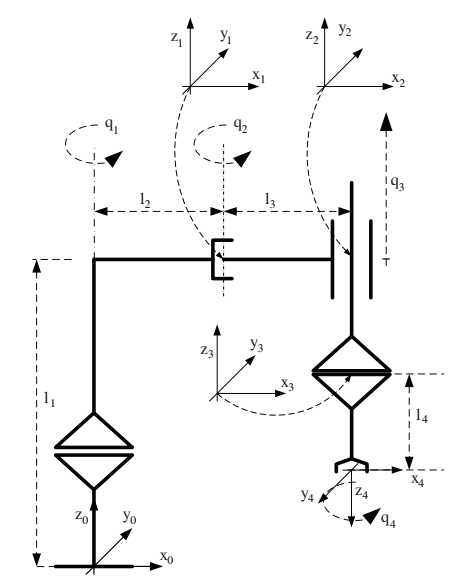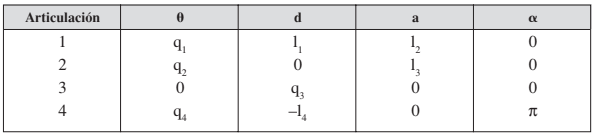

% Solving for [x_dot y_dot z_dot phi_dot theta_dot psi_dot]'
% Relates articular velocities (q1,...qn) with location velocities (x_dot, y_dot,...psi_dot)
syms q1 q2 q3 q4 l1 l2 l3 l4

R = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
T1 = HTM(R);
p1 = [0 0 l1]';
T2 = HTM(eye(3), p1);
p2 = [l2 0 0]';
T3 = HTM(eye(3), p2);

A01 = T1 * T2 * T3

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & \bar{l_{2}}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & \bar{l_{2}}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1];
T1 = HTM(R);
p = [l3 0 0]';
T2 = HTM(eye(3), p);

A12 = T1 * T2

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & \bar{l_{3}}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & \bar{l_{3}}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [0 0 q3]';
T1 = HTM(eye(3), p);

A23 = T1

$$A23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \bar{q_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(q4) -sin(q4) 0; sin(q4) cos(q4) 0; 0 0 1];
T1 = HTM(R1);
p = [0 0 -l4]';
T2 = HTM(eye(3), p);
R2 = rotx(180);     % pi
T3 = HTM(R2);

A34 = T1 * T2 * T3

$$A34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & -1 & -\bar{l_{4}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A04 = simplify(A01 * A12 * A23 * A34)

$$A04 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & 0 & \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}}\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & -\cos\left(q_{1}+q_{2}+q_{4}\right) & 0 & \bar{l_{2}}\,\sin\left(q_{1}\right)+\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}}\\ 0 & 0 & -1 & \bar{l_{1}}-\bar{l_{4}}+\bar{q_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Direct kinematics
x = A04(1,4)

$$x = \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}}$$

y = A04(2,4)

$$y = \bar{l_{2}}\,\sin\left(q_{1}\right)+\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}}$$

z = A04(3,4)

$$z = \bar{l_{1}}-\bar{l_{4}}+\bar{q_{3}}$$

phi = q1 + q2 + q4;
theta = 180;         % pi
psi = 180;           % pi

% Euler angles WVW
R1 = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
R2 = roty(theta);
R3 = rotz(psi);

all(all(  R1 * R2 * R3 == A04(1:3,1:3)  ))

ans = logical
   1


% EXAMPLE 1
ART_pos = [q1 q2 q3 q4];
FA_pos = [x y z phi theta psi];

% Completing Analitic Jacobian J
J = jacobian(FA_pos, ART_pos)

$$J = \left(\begin{array}{cccc} -\bar{l_{2}}\,\sin\left(q_{1}\right)-\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & -\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & \cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ 0 & 0 & 1 & 0\\ 1 & 1 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Example 1 data
ART_pos = [pi/6 pi/4 0.75 0];       % [rad rad m rad]
ART_vel = [pi/2 pi/2 1 pi/4]';      % [rad/s rad/s m/s rad/s]
J = vpa(subs(J, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$J = \left(\begin{array}{cccc} -1.47 & -0.966 & 0 & 0\\ 1.12 & 0.259 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 1.0 & 1.0 & 0 & 1.0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Final actuator's location velocities
FA_vels = vpa(J * ART_vel, 3)

$$FA\_vels = \left(\begin{array}{c} -3.82\\ 2.17\\ 1.0\\ 3.93\\ 0\\ 0 \end{array}\right)$$

x_dot = FA_vels(1)

$$x\_dot = -3.819943643175065517425537109375$$

y_dot = FA_vels(2)

$$y\_dot = 2.1734535338473506271839141845703$$

z_dot = FA_vels(3)

$$z\_dot = 1.0$$

phi_dot = FA_vels(4)

$$phi\_dot = 3.9269908169517293572425842285156$$

theta_dot = FA_vels(5)

$$theta\_dot = 0$$

psi_dot = FA_vels(6)

$$psi\_dot = 0$$

% EXAMPLE 2
ART_pos = [q1 q2 q3 q4];
FA_pos = [x y z phi theta psi];

%Completing Analitic Jacobian J
J = jacobian(FA_pos, ART_pos);
% Example 2 data
ART_pos = [pi/3 pi/2 0.75 0];       % [rad rad m rad]
J = vpa(subs(J, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$J = \left(\begin{array}{cccc} -1.37 & -0.5 & 0 & 0\\ -0.366 & -0.866 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 1.0 & 1.0 & 0 & 1.0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Final actuator's location velocities
FA_vels = vpa(J * ART_vel, 3)

$$FA\_vels = \left(\begin{array}{c} -2.93\\ -1.94\\ 1.0\\ 3.93\\ 0\\ 0 \end{array}\right)$$

x_dot = FA_vels(1)

$$x\_dot = -2.9311458499869331717491149902344$$

y_dot = FA_vels(2)

$$y\_dot = -1.9353008829348254948854446411133$$

z_dot = FA_vels(3)

$$z\_dot = 1.0$$

phi_dot = FA_vels(4)

$$phi\_dot = 3.9269908169517293572425842285156$$

theta_dot = FA_vels(5)

$$theta\_dot = 0$$

psi_dot = FA_vels(6)

$$psi\_dot = 0$$

## Geometric Jacobian

% Solving for [vx vy vz wx wy wz]'
% Relates articular velocities (q1,...qn) with linear and angular velocities (vx, vy,...wz)
syms q1_dot q2_dot q3_dot q4_dot

px = A04(1,4)

$$px = \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}}$$

py = A04(2,4)

$$py = \bar{l_{2}}\,\sin\left(q_{1}\right)+\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}}$$

pz = A04(3,4)

$$pz = \bar{l_{1}}-\bar{l_{4}}+\bar{q_{3}}$$

p = [px py pz];
ART_pos = [q1 q2 q3 q4];

% Calculating Jv
Jv = jacobian(p, ART_pos)

$$Jv = \left(\begin{array}{cccc} -\bar{l_{2}}\,\sin\left(q_{1}\right)-\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & -\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & \cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

R = A04(1:3,1:3)

$$R = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & 0\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & -\cos\left(q_{1}+q_{2}+q_{4}\right) & 0\\ 0 & 0 & -1 \end{array}\right)$$

% Taking derivative with respect to q1, q2 or q4 will result in the same result
R_dot = diff(R, q1) * (q1_dot + q2_dot + q4_dot)

$$R\_dot = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{4}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & \cos\left(q_{1}+q_{2}+q_{4}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & 0\\ \cos\left(q_{1}+q_{2}+q_{4}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

Omega = simplify(R_dot * R)

$$Omega = \left(\begin{array}{ccc} 0 & -q_{\dot{1}}-q_{\dot{2}}-q_{\dot{4}} & 0\\ q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

wx = Omega(3,2)

$$wx = 0$$

wy = Omega(1,3)

$$wy = 0$$

wz = Omega(2,1)

$$wz = q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}$$

w = [wx wy wz];
ART_vel = [q1_dot q2_dot q3_dot q4_dot];

% Calculating Jw
Jw = jacobian(w, ART_vel)

$$Jw = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$

% Completing Geometric Jacobian J
J = [Jv; Jw]

$$J = \left(\begin{array}{cccc} -\bar{l_{2}}\,\sin\left(q_{1}\right)-\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & -\sin\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ \bar{l_{2}}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & \cos\left(q_{1}+q_{2}\right)\,\bar{l_{3}} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$

% Using data from example in geometric jacobian
ART_pos = [pi/6 pi/4 0.75 0];       % [rad rad m rad]
ART_vel = [pi/2 pi/2 1 pi/4]';      % [rad/s rad/s m/s rad/s]
J = vpa(subs(J, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$J = \left(\begin{array}{cccc} -1.47 & -0.966 & 0 & 0\\ 1.12 & 0.259 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1.0 & 1.0 & 0 & 1.0 \end{array}\right)$$

% Calculating Linear and Angular Velocities
LA_vel = vpa(J * ART_vel, 3)

$$LA\_vel = \left(\begin{array}{c} -3.82\\ 2.17\\ 1.0\\ 0\\ 0\\ 3.93 \end{array}\right)$$